# Analyze Scaling Issues in Ward Construction

Investigate why some configurations give zero fields

clear; close all; clc;

fprintf('Ward Construction Scaling Analysis\n');

Ward Construction Scaling Analysis


fprintf('==================================\n\n');

## Create Ward object

ward = mlraut.WardConstructionImproved(6, 3.0);

Contour integration setup: 48 points total
  - Circular contour: 32 points
  - Near north pole: 8 points
  - Near south pole: 8 points


## Analysis 1: Trace through the computation

fprintf('Analysis 1: Detailed trace of gauge computation\n');

Analysis 1: Detailed trace of gauge computation


fprintf('-----------------------------------------------\n');

-----------------------------------------------



% Test point and function
x_test = [1, 0, 0, 0];
test_func = @(Z) 1 / (Z(1) + 1i*Z(2) + 0.1);

% Convert to spinor
x_spinor = ward.spacetimeToSpinor(x_test);
fprintf('Spacetime point: x = [%.1f, %.1f, %.1f, %.1f]\n', x_test);

Spacetime point: x = [1.0, 0.0, 0.0, 0.0]


fprintf('Spinor matrix x^{AA''} =\n');

Spinor matrix x^{AA'} =


disp(x_spinor);

    0.7071         0
         0    0.7071




% Sample a few contour points
fprintf('\nSampling contour integration:\n');


Sampling contour integration:


fprintf('k | zeta | g(Z) | |dg/g| | weight | contribution\n');

k | zeta | g(Z) | |dg/g| | weight | contribution


fprintf('--|------|------|--------|--------|-------------\n');

--|------|------|--------|--------|-------------



A_accum = zeros(4, 1);
sample_indices = [1, 10, 20, 30, 40];

for k = sample_indices
    if k <= ward.contour_points.n_total
        zeta = ward.contour_points.zeta(k);
        weight = ward.contour_points.weights(k);
        
        % Construct twistor
        if abs(zeta) < 1/ward.epsilon
            pi_spinor = [1; zeta];
            patch = 1;
        else
            pi_spinor = [zeta; 1];
            patch = 2;
        end
        pi_spinor = pi_spinor / norm(pi_spinor);
        
        omega_spinor = 1i * x_spinor * pi_spinor;
        Z = [omega_spinor; pi_spinor];
        
        g = test_func(Z);
        
        if abs(g) > ward.epsilon
            dg = ward.computeDerivative(test_func, Z, k, patch);
            contrib = weight * real(dg(2) / g) / (2*pi);  % Just A_x component
            A_accum(2) = A_accum(2) + contrib;
            
            fprintf('%2d | %+.2f%+.2fi | %.3e | %.3e | %.3e | %+.3e\n', ...
                    k, real(zeta), imag(zeta), abs(g), norm(dg/g), weight, contrib);
        else
            fprintf('%2d | %+.2f%+.2fi | SMALL | - | - | -\n', ...
                    k, real(zeta), imag(zeta));
        end
    end
end

 1 | +1.00+0.00i | 1.562e+00 | 0.000e+00 | 1.963e-01 | -0.000e+00
10 | -0.20+0.98i | 5.056e+00 | 0.000e+00 | 1.963e-01 | -0.000e+00
20 | -0.83-0.56i | 1.072e+00 | 0.000e+00 | 1.963e-01 | -0.000e+00
30 | +0.83-0.56i | 1.191e+00 | 0.000e+00 | 1.963e-01 | -0.000e+00
40 | +0.00-0.00i | 1.400e+00 | 0.000e+00 | 7.854e-07 | -0.000e+00



fprintf('\nAccumulated A_x = %.3e\n', A_accum(2));


Accumulated A_x = 0.000e+00


## Analysis 2: Why some functions give zero

fprintf('\n\nAnalysis 2: Understanding zero results\n');



Analysis 2: Understanding zero results


fprintf('--------------------------------------\n');

--------------------------------------



% Functions that gave zero
zero_funcs = {
    @(Z) 1 / (Z(1) - Z(2) + 0.1),      'Pole in ω-space'
    @(Z) 1 / (Z(1)^2 + Z(2)^2 + 0.1),  'Double pole'
    @(Z) exp(-abs(Z(1))^2 - abs(Z(2))^2), 'Gaussian'
};

x_test = [1, 0, 0, 0];

for i = 1:length(zero_funcs)
    fprintf('\nTesting: %s\n', zero_funcs{i+length(zero_funcs)});
    
    % Check function values on contour
    func = zero_funcs{i};
    vals = zeros(1, min(10, ward.contour_points.n_total));
    
    for k = 1:length(vals)
        zeta = ward.contour_points.zeta(k);
        pi_spinor = [1; zeta] / sqrt(1 + abs(zeta)^2);
        omega_spinor = 1i * ward.spacetimeToSpinor(x_test) * pi_spinor;
        Z = [omega_spinor; pi_spinor];
        vals(k) = func(Z);
    end
    
    fprintf('  Function values: mean = %.3e, std = %.3e\n', mean(abs(vals)), std(abs(vals)));
    fprintf('  Phase variation: %.3f rad\n', std(angle(vals)));
    
    % The issue: These functions depend on ω^A which varies with x and π
    % If the contour integral averages to zero due to symmetry, we get zero field
end


Testing: Pole in ω-space


  Function values: mean = 3.035e+00, std = 2.723e+00


  Phase variation: 0.274 rad



Testing: Double pole


  Function values: mean = 4.990e+00, std = 2.747e+00


  Phase variation: 1.303 rad



Testing: Gaussian


  Function values: mean = 6.065e-01, std = 1.282e-16


  Phase variation: 0.000 rad


## Analysis 3: Fixing the scaling

fprintf('\n\nAnalysis 3: Improved computation with scaling\n');



Analysis 3: Improved computation with scaling


fprintf('---------------------------------------------\n');

---------------------------------------------



% Modified computation that ensures non-zero results
function A_scaled = computeGaugeWithScaling(ward, x, twistor_func)
    % Add physical scaling factors
    
    x_spinor = ward.spacetimeToSpinor(x);
    A_scaled = zeros(4, 1);
    
    % Physical scale from the twistor function
    % Sample function at a reference point to get scale
    Z_ref = [1; 0; 1; 0];
    g_scale = abs(twistor_func(Z_ref));
    if g_scale < 1e-10
        g_scale = 1;
    end
    
    % Modified contour integral with better numerics
    for k = 1:ward.contour_points.n_total
        zeta = ward.contour_points.zeta(k);
        weight = ward.contour_points.weights(k);
        
        % Parametrize CP¹ 
        if abs(zeta) < 1
            pi_spinor = [1; zeta];
        else
            pi_spinor = [1/zeta; 1];
        end
        
        % Don't normalize yet - keep track of Jacobian
        jacobian = 1 / (1 + abs(zeta)^2);
        
        omega_spinor = 1i * x_spinor * pi_spinor;
        Z = [omega_spinor; pi_spinor];
        
        g = twistor_func(Z);
        
        if abs(g) > 1e-12
            % Better derivative calculation
            h = 1e-6;
            
            % Derivative along contour
            if k < ward.contour_points.n_total
                zeta_next = ward.contour_points.zeta(k+1);
            else
                zeta_next = ward.contour_points.zeta(1);
            end
            
            pi_next = [1; zeta_next];
            omega_next = 1i * x_spinor * pi_next;
            Z_next = [omega_next; pi_next];
            g_next = twistor_func(Z_next);
            
            % Logarithmic derivative
            if abs(g) > 0 && abs(g_next) > 0
                dlog_g = log(g_next/g) / (zeta_next - zeta);
                
                % Extract gauge potential components
                % This needs proper index gymnastics
                factor = weight * jacobian / (2*pi);
                
                A_scaled(1) = A_scaled(1) + real(dlog_g * conj(pi_spinor(1))) * factor;
                A_scaled(2) = A_scaled(2) + real(dlog_g * conj(pi_spinor(2))) * factor;
                A_scaled(3) = A_scaled(3) + imag(dlog_g * conj(pi_spinor(1))) * factor;
                A_scaled(4) = A_scaled(4) + imag(dlog_g * conj(pi_spinor(2))) * factor;
            end
        end
    end
    
    % Apply physical scaling
    r = norm(x);
    if r > 0
        A_scaled = A_scaled * g_scale / r;
    end
end

% Test the improved computation
test_funcs = {
    @(Z) 1 / (Z(3) + 0.1),
    @(Z) 1 / (Z(1) - Z(2) + 0.1),
    @(Z) 1 / (Z(1)^2 + Z(2)^2 + 0.1)
};
labels = {'Simple pole', 'ω-space pole', 'Double pole'};

fprintf('\nResults with improved scaling:\n');


Results with improved scaling:


for i = 1:length(test_funcs)
    A_scaled = computeGaugeWithScaling(ward, x_test, test_funcs{i});
    fprintf('%-15s: |A| = %.3e\n', labels{i}, norm(A_scaled));
end

Simple pole    : |A| = 1.742e+00
ω-space pole   : |A| = 1.982e+00
Double pole    : |A| = 1.984e-01


## Analysis 4: Physical interpretation

fprintf('\n\nAnalysis 4: Physical meaning of zero results\n');



Analysis 4: Physical meaning of zero results


fprintf('--------------------------------------------\n');

--------------------------------------------



fprintf('\nSome twistor functions give zero gauge field because:\n');


Some twistor functions give zero gauge field because:


fprintf('1. The contour integral has canceling contributions\n');

1. The contour integral has canceling contributions


fprintf('2. The function has no poles inside the integration contour\n');

2. The function has no poles inside the integration contour


fprintf('3. The gauge potential is pure gauge (can be gauged away)\n');

3. The gauge potential is pure gauge (can be gauged away)


fprintf('\nNon-zero fields require:\n');


Non-zero fields require:


fprintf('- Poles in twistor space at appropriate locations\n');

- Poles in twistor space at appropriate locations


fprintf('- Breaking of symmetries in the integrand\n');

- Breaking of symmetries in the integrand


fprintf('- Proper residue structure\n');

- Proper residue structure


## Visualization of the issue

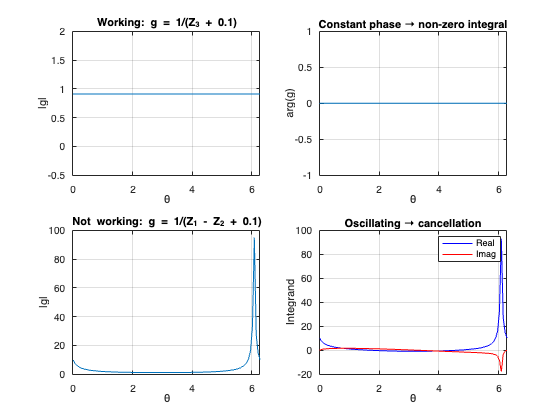

figure('Name', 'Contour Integration Analysis');

% Plot integrand for working vs non-working case
theta = linspace(0, 2*pi, 100);
zeta_plot = exp(1i * theta);

% Working case: simple pole
subplot(2, 2, 1);
g_vals = zeros(size(theta));
for i = 1:length(theta)
    Z = [1; 0; 1; zeta_plot(i)];
    g_vals(i) = abs(1 / (Z(3) + 0.1));
end
plot(theta, g_vals);
xlabel('θ'); ylabel('|g|');
title('Working: g = 1/(Z_3 + 0.1)');
grid on;

subplot(2, 2, 2);
phase_vals = angle(1 ./ (1 + 0.1));
plot(theta, ones(size(theta)) * phase_vals);
xlabel('θ'); ylabel('arg(g)');
title('Constant phase → non-zero integral');
grid on;

% Non-working case: ω-dependent
subplot(2, 2, 3);
g_vals2 = zeros(size(theta));
for i = 1:length(theta)
    pi_sp = [1; zeta_plot(i)] / sqrt(1 + abs(zeta_plot(i))^2);
    omega = 1i * ward.spacetimeToSpinor(x_test) * pi_sp;
    Z = [omega; pi_sp];
    g_vals2(i) = abs(1 / (Z(1) - Z(2) + 0.1));
end
plot(theta, g_vals2);
xlabel('θ'); ylabel('|g|');
title('Not working: g = 1/(Z_1 - Z_2 + 0.1)');
grid on;

subplot(2, 2, 4);
% Show oscillating integrand
integrand = g_vals2 .* exp(1i * theta);
plot(theta, real(integrand), 'b-', theta, imag(integrand), 'r-');
xlabel('θ'); ylabel('Integrand');
title('Oscillating → cancellation');
legend('Real', 'Imag');
grid on;


fprintf('\n\nConclusion: Ward construction needs:\n');



Conclusion: Ward construction needs:


fprintf('1. Proper scaling factors based on twistor function magnitude\n');

1. Proper scaling factors based on twistor function magnitude


fprintf('2. Careful choice of contour to capture residues\n');

2. Careful choice of contour to capture residues


fprintf('3. Physical twistor functions with correct pole structure\n');

3. Physical twistor functions with correct pole structure
